# Refining Feature Detection

In this reading, you will detect corner features on this image of a chessboard table using the Harris-Stephens algorithm, as shown below: 

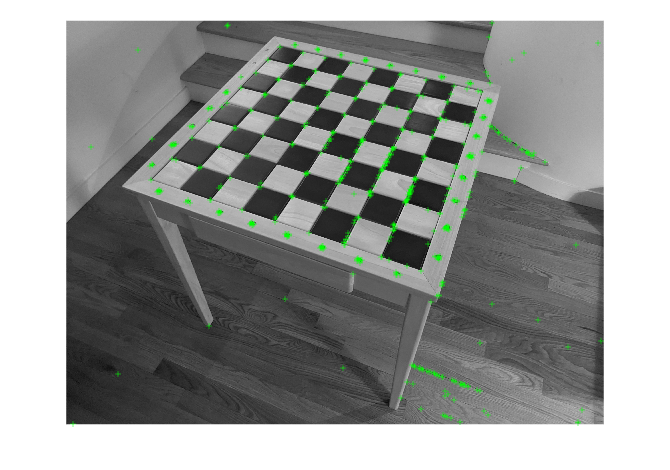

% Read in the image and convert to grayscale
chesstableRGB = imread("chesstable.jpg");
chesstable = im2gray(chesstableRGB);

% Detect corner features
corners = detectHarrisFeatures(chesstable);

% Display the image and features
imshow(chesstable)
hold on
plot(corners)
hold off

Recall from the previous discussion prompt that you aren't interested in all the features in the image, only the ones on the face of the table. This reading will guide you through a few techniques you can use to filter and refine the detected features. 

## Selecting Strongest Features

Start by using the `selectStrongest` function to only visualize the 300 "strongest" features in the image, or the ones that have the highest metric values.

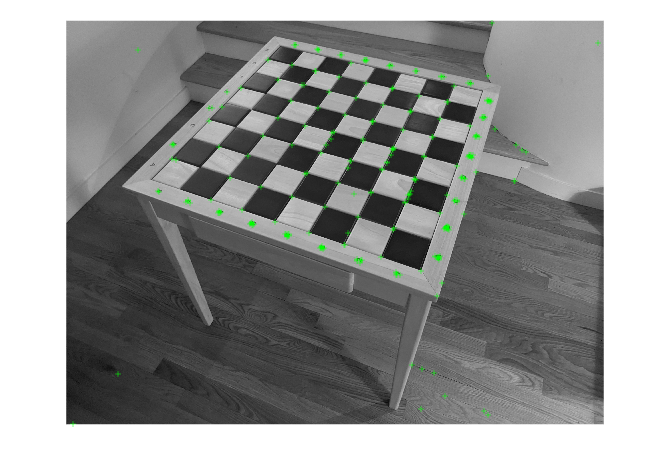

imshow(chesstable)
hold on
% Display strongest corner features
plot(selectStrongest(corners,300))
hold off

As you change the number of strongest features, notice that the features on the surface of the chess table are not always the strongest ones, so this technique isn't the best option for us here. Let's try another approach using one of the options of `detectHarrisFeatures`.

## Changing Filter Size

You may notice that a lot of the corners detected are unexpected due to the high resolution of the image. You can change the level of detail used to detect features by using the `"FilterSize"` option of `detectHarrisFeatures`. This value represents the Gaussian filter dimension used to smooth the gradient of the input image. In other words, increasing the value from its default of 5 to another odd integer will detect features in the more smoothed, or blurred, version of the input image.

You can visualize the results for different values of `"FilterSize"` below.

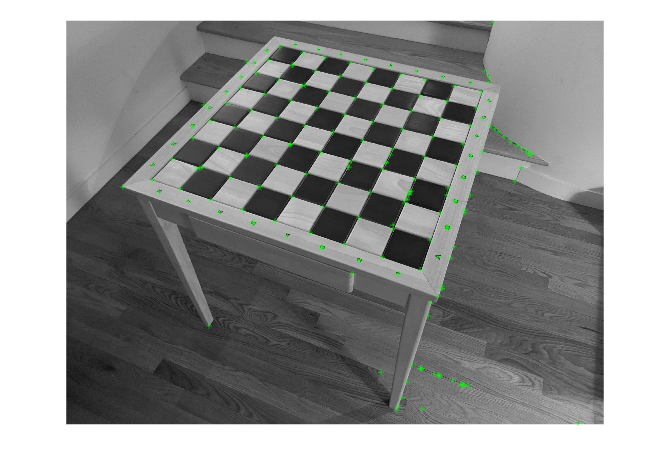

% Detect corner features using different values for FilterSize
chessCorners = detectHarrisFeatures(chesstable,"FilterSize",27);

% Display the result
imshow(chesstable)
hold on
plot(chessCorners)
hold off

As `"FilterSize"` gets larger, the smoothed image looks increasingly different from the original image. The detected features may not look like the ones we expect to see, but the number of detected features does tend to decrease. However, we're still unable to focus only on the features on the chessboard surface. There's one more important approach to try-- defining a specific region of interest.

## Region of Interest

Another possibility is to use the region of interest, or `"ROI"`, option to ensure your algorithm only focuses on a specific area of the image. Use the below code to create your region of interest, and then detect corner features only in that region

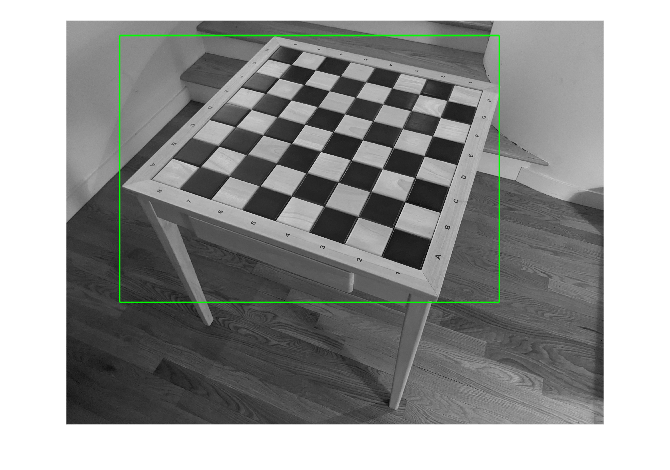

% Choose your region of interest
% The first 2 values represent the location of the upper-left corner.
% The last 2 values represent its width and height.
chesstableROI = [400,110,2850,2000];

% Display rectangle representing that region
imshow(chesstable)
rectangle("Position",chesstableROI,"EdgeColor","g")

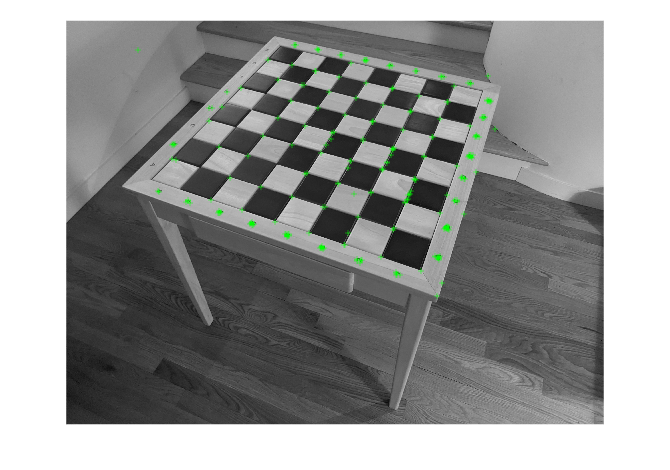

% Detect features in that region
cornersROI = detectHarrisFeatures(chesstable,"ROI",chesstableROI);

% Visualize the strongest features
imshow(chesstable)
hold on
plot(selectStrongest(cornersROI,290))
hold off

This looks much better! Almost every detected feature is now on the table surface. 

Other detection functions also have different options like `"ROI"`, so when you're not satisfied with the results from your detection step, be sure to check out the documentation to see which options you can use to fine tune your results.

## The Impact of Scale Invariance on Harris

one of the biggest challenges in feature detection is **scale variation**. This means that if we view an object from different distances, or change its size within an image, the algorithm should still be able to recognize it. The **Harris corner detector**, by its nature, is sensitive to scale. If we shrink or enlarge an image, it might not be able to find the same features.

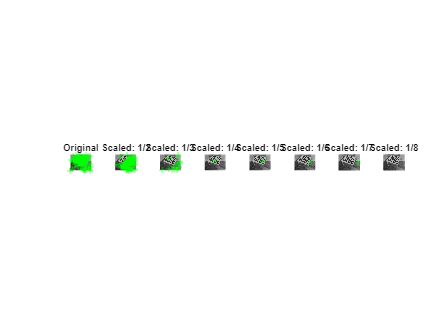

im = chesstable;
points = detectHarrisFeatures(im);

figure;
subplot(1,8,1);
imshow(im);
hold on;
plot(points);
title('Original');

for i = 2:8
    im_sc = imresize(im, 1/i);
    points = detectHarrisFeatures(im);
    subplot(1,8,i);
    imshow(im_sc);
    hold on;
    plot(points);
    title(['Scaled: 1/' num2str(i)]);
end

As you can see, as the image gets smaller, the number and positions of Harris changes significantly. This is where the need for more advanced algorithms like SIFT and SURF comes into play.

The Harris corner detector is also sensitive to other image transformations beyond just scale. While it exhibits some robustness to **rotation**, large rotations can still cause issues. For instance, if a corner is rotated significantly, its local intensity pattern might change enough to prevent the Harris detector from identifying it consistently.

Furthermore, the Harris detector is generally not robust to significant changes in **illumination**. A drastic change in lighting conditions can alter the intensity gradients around a corner, making it undetectable. Similarly, **affine transformations** (which include scaling, rotation, shearing, and translation) can severely impact the Harris detector's performance, as the local neighborhood around a corner can be distorted in ways that are not accounted for by the algorithm.

## SIFT (Scale-Invariant Feature Transform)

SIFT is one of the most powerful feature recognition algorithms.

detectSIFTFeatures has fewer parameters to be set directly by the user, as most of the steps are done automatically and optimally. but you can explor more with seting "NumLayersInOctave"', "ContrastThreshold", "EdgeThreshold", "sigma".

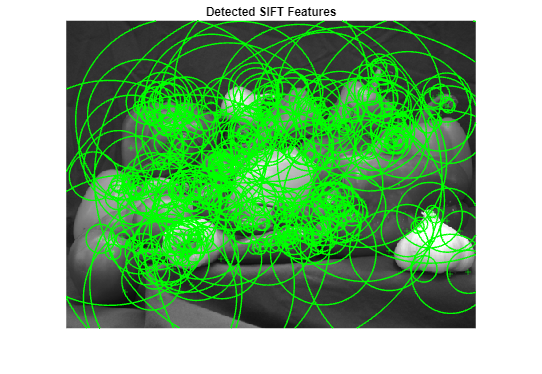

peppers = imread("peppers.png");
peppers = im2gray(peppers);
points_sift = detectSIFTFeatures(peppers);

figure;
imshow(peppers);
hold on;
plot(points_sift);
title('Detected SIFT Features');
hold off;

## The Impact of Scale Invariance on SIFT

introduced by David Lowe in 1999 and is considered a landmark in computer vision. Here are its key features:

- **Scale Invariance:** It detects feature points at various scales by constructing an **image pyramid** and applying Gaussian filters of different sizes.

- **Rotation Invariance:** For each feature point, it computes a **dominant orientation** and builds the feature's descriptor relative to that orientation.

- **Robustness to Illumination Changes and Noise:** It constructs descriptors in a way that makes them robust to minor changes in illumination and the presence of noise.

- **Robust Descriptors:** Each feature point is described by a **128-dimensional vector** that includes spatial and gradient information around that point.

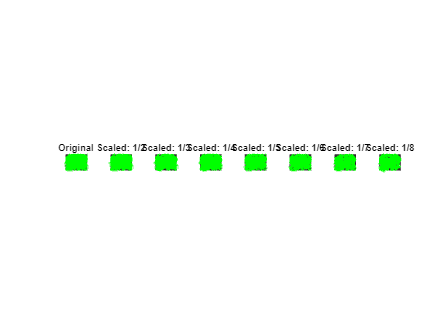

im = peppers;
points = detectSIFTFeatures(im);

figure;
subplot(1,8,1);
imshow(im);
hold on;
plot(points);
title('Original');

for i = 2:8
    im_sc = imresize(im, 1/i);
    points = detectSIFTFeatures(im_sc);
    subplot(1,8,i);
    imshow(im_sc);
    hold on;
    plot(points);
    title(['Scaled: 1/' num2str(i)]);
end

## SURF (Speeded Up Robust Features)

Introduced by Herbert Bay and colleagues in 2006, SURF is essentially a faster and more optimized version of SIFT. The main goal of SURF was to greatly increase the computational speed while maintaining the accuracy of SIFT.

points_surf = detectSURFFeatures(chesstable);

figure;
imshow(chesstable);
hold on;
plot(selectStrongest(points_surf, 500));
title('Detected SURF Features (Strongest 500)');
hold off;

## Further Exploration

In this reading, we focused on refining the results from the Harris detection algorithm, but there are many other detection algorithms you could explore instead! Refer to the documentation to learn more:

- [FAST](https://www.mathworks.com/help/vision/ref/detectfastfeatures.html)

- [Min Eigenvalue](https://www.mathworks.com/help/vision/ref/detectmineigenfeatures.html)

- [BRISK](https://www.mathworks.com/help/vision/ref/detectbriskfeatures.html)

- [ORB](https://www.mathworks.com/help/vision/ref/detectorbfeatures.html)

- [KAZE](https://www.mathworks.com/help/vision/ref/detectkazefeatures.html)

- MSER